%% Steepest Descent Method with checkpoints and plot
% Save this file as `steepest_descent_live_script.m` and open it in MATLAB.
% The section breaks (%%) make it easy to run one step at a time.

clear; clc;
format compact;

%% Problem definition
% Change f, x0, or the symbols here to reuse the script on another problem.
syms x1 x2 real
f = (x1-1)^2 + 2*x2^2;

x0 = [3; 1];
maxIter = 20;
tolGrad  = 1e-10;

fprintf('Objective function f(x):\n');

Objective function f(x):


disp(f)

$${\left(x_{1}-1\right)}^{2}+2\,{x_{2}}^{2}$$

fprintf('Initial point x0 = [%.6g, %.6g]^T\n', x0(1), x0(2));

Initial point x0 = [3, 1]^T



%% Symbolic gradient
c = gradient(f, [x1, x2]);

fprintf('\nSymbolic gradient c(x) = ∇f(x):\n');


Symbolic gradient c(x) = ∇f(x):


disp(c)

$$\left(\begin{array}{c} 2\,x_{1}-2\\ 4\,x_{2} \end{array}\right)$$


c0 = double(subs(c, [x1 x2], x0.'));

fprintf('Gradient at x0:\n');

Gradient at x0:


disp(c0)

     4
     4


fprintf('||grad f(x0)||_2 = %.12g\n', norm(c0, 2));

||grad f(x0)||_2 = 5.65685424949



%% Check convergence at the starting point
if norm(c0, 2) < tolGrad
    disp('Initial point already satisfies the convergence criterion.');
else
    disp('Initial point does not yet satisfy the convergence criterion.');
end

Initial point does not yet satisfy the convergence criterion.



%% Compute the steepest descent direction
% For steepest descent, the search direction is the negative gradient.
d = -c0;

fprintf('\nSearch direction d = -c(x0):\n');


Search direction d = -c(x0):


disp(d)

    -4
    -4



isDescent = (c0.' * d) < 0;
fprintf('c(x0)^T d = %.12g\n', c0.' * d);

c(x0)^T d = -32


if isDescent
    disp('This is a descent direction.');
else
    disp('This is NOT a descent direction.');
end

This is a descent direction.



%% Exact line search along the steepest descent direction
syms alpha real
xAlpha = x0 + alpha*d;
fAlpha = simplify(subs(f, [x1 x2], xAlpha.'));
dfAlpha = simplify(diff(fAlpha, alpha));
alphaStar = solve(dfAlpha == 0, alpha);
alphaStar = double(alphaStar);

fprintf('\nLine search function f(alpha):\n');


Line search function f(alpha):


disp(fAlpha)

$$2\,{\left(4\,\alpha -1\right)}^{2}+{\left(4\,\alpha -2\right)}^{2}$$

fprintf('Derivative df/dalpha:\n');

Derivative df/dalpha:


disp(dfAlpha)

$$96\,\alpha -32$$

fprintf('Candidate step size alpha*:\n');

Candidate step size alpha*:


disp(alphaStar)

    0.3333



% If multiple roots appear, choose the real one closest to positive.
alphaStar = alphaStar(isreal(alphaStar));
alphaStar = alphaStar(alphaStar >= 0);
if isempty(alphaStar)
    error('No nonnegative real step size found from the line search.');
end
alphaStar = alphaStar(1);

%% Update the iterate
x1_new = x0 + alphaStar * d;
c1 = double(subs(c, [x1 x2], x1_new.'));

fprintf('\nNew iterate x1:\n');


New iterate x1:


disp(x1_new)

    1.6667
   -0.3333


fprintf('Gradient at x1:\n');

Gradient at x1:


disp(c1)

    1.3333
   -1.3333


fprintf('Objective value at x1: %.12g\n', double(subs(f, [x1 x2], x1_new.')))

Objective value at x1: 0.666666666667


fprintf('||grad f(x1)||_2 = %.12g\n', norm(c1, 2));

||grad f(x1)||_2 = 1.88561808316


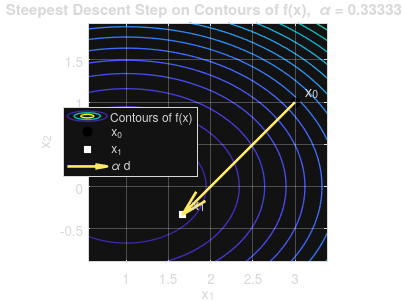


%% Plot objective contours and steepest-descent step
% This plot auto-scales around x0 and x1_new, so it stays readable for
% different functions and step sizes.

fHandle = matlabFunction(f, 'Vars', [x1, x2]);

pts = [x0, x1_new];
xmin = min(pts(1,:)); xmax = max(pts(1,:));
ymin = min(pts(2,:)); ymax = max(pts(2,:));

dx = xmax - xmin;
dy = ymax - ymin;
stepSize = norm(x1_new - x0);

% Ensure a nonzero, visible plotting window even if the step is tiny.
baseSpan = max([dx, dy, stepSize, 1]);
pad = 0.75 * baseSpan;

xRange = [xmin - pad, xmax + pad];
yRange = [ymin - pad, ymax + pad];

% Build grid for contours
nGrid = 250;
xv = linspace(xRange(1), xRange(2), nGrid);
yv = linspace(yRange(1), yRange(2), nGrid);
[Xg, Yg] = meshgrid(xv, yv);

Zg = fHandle(Xg, Yg);

figure('Color','w');
contour(Xg, Yg, Zg, 25, 'LineWidth', 1);
hold on;
grid on;
axis equal;
xlim(xRange);
ylim(yRange);

% Plot x0 and x1
plot(x0(1), x0(2), 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 7);
plot(x1_new(1), x1_new(2), 'ks', 'MarkerFaceColor', 'w', 'MarkerSize', 8);

% Plot the actual step vector alpha*d
stepVec = x1_new - x0;
quiver(x0(1), x0(2), stepVec(1), stepVec(2), 0, ...
    'LineWidth', 2, 'MaxHeadSize', 0.7);

% Labels
text(x0(1), x0(2), '  x_0', 'FontSize', 11, 'VerticalAlignment', 'bottom');
text(x1_new(1), x1_new(2), '  x_1', 'FontSize', 11, 'VerticalAlignment', 'bottom');
title(sprintf('Steepest Descent Step on Contours of f(x),  \\alpha = %.6g', alphaStar));
xlabel('x_1');
ylabel('x_2');

legend('Contours of f(x)', 'x_0', 'x_1', '\alpha d', 'Location', 'best');


%% Summary for this step
fprintf('\nSummary of one steepest descent step:\n');


Summary of one steepest descent step:


fprintf('x0 = [%.6g, %.6g]^T\n', x0(1), x0(2));

x0 = [3, 1]^T


fprintf('d  = [%.6g, %.6g]^T\n', d(1), d(2));

d  = [-4, -4]^T


fprintf('alpha* = %.12g\n', alphaStar);

alpha* = 0.333333333333


fprintf('x1 = [%.6g, %.6g]^T\n', x1_new(1), x1_new(2));

x1 = [1.66667, -0.333333]^T



if norm(c1, 2) < tolGrad
    disp('Convergence criterion satisfied.');
else
    disp('Convergence criterion not yet satisfied.');
end

Convergence criterion not yet satisfied.



%% Optional: repeat automatically for more iterations
% Uncomment this section if you want the script to continue until convergence.
%
%xk = x0;
%for k = 1:maxIter
%    ck = double(subs(c, [x1 x2], xk.'));
%    if norm(ck, 2) < tolGrad
%        fprintf('Converged at iteration %d.\n', k-1);
%        break
%    end
%
%    % Steepest descent direction
%    dk = -ck;
%
%    % Exact line search: minimize f(xk + a*dk)
%    syms a real
%    fA = simplify(subs(f, [x1 x2], (xk + a*dk).'));
%    dF = simplify(diff(fA, a));
%    aStar = double(solve(dF == 0, a));
%    aStar = aStar(isreal(aStar) & aStar >= 0);
%    if isempty(aStar)
%        error('No nonnegative real step size found at iteration %d.', k);
%    end
%    aStar = aStar(1);
%
%    % Update
%    xk = xk + aStar * dk;
%    fprintf('Iter %d: x = [%.6g, %.6g]^T, ||grad|| = %.12g, alpha = %.12g\n', ...
%        k, xk(1), xk(2), norm(double(subs(c,[x1 x2],xk.')),2), aStar);
%end
